%% State-Space Basics: Line Follower DC Motor
clear; clc; close all;


%% Parameters
R = 10;           % Resistance [Ω]
L = 5e-3;         % Inductance [H]
Ke = 0.12;        % Back-EMF [V·s/rad]
Kt = 0.12;        % Torque [N·m/A]
J = 1.2e-4;       % Inertia [kg·m²]
b = 1e-3;         % Friction [N·m·s/rad]


%% Build Continuous-Time Model
% States: x = [i; ω]
% Input: u = V
% Output: y = ω

A = [-R/L  -Ke/L;
     Kt/J  -b/J];

B = [1/L; 0];

C = [0 1];

D = 0;

sys_c = ss(A, B, C, D);

disp('A:'); disp(A);

A:
   1.0e+03 *

   -2.0000   -0.0240
    1.0000   -0.0083



disp('B:'); disp(B);

B:
   200
     0



disp('C:'); disp(C);

C:
     0     1



disp('D:'); disp(D);

D:
     0



%% Stability (Eigenvalues)
lambda = eig(A);
disp('Eigenvalues:'); disp(lambda);

Eigenvalues:
   1.0e+03 *

   -1.9879
   -0.0205



disp(['Stable: ' num2str(all(real(lambda) < 0))]);

Stable: 1


%% Controllability
Co = ctrb(A, B);
rank_Co = rank(Co);
disp(['Controllability rank: ' num2str(rank_Co) '/' num2str(size(A,1))]);

Controllability rank: 2/2


disp(['Controllable: ' num2str(rank_Co == size(A,1))]);

Controllable: 1


%% Observability
Ob = obsv(A, C);
rank_Ob = rank(Ob);
disp(['Observability rank: ' num2str(rank_Ob) '/' num2str(size(A,1))]);

Observability rank: 2/2


disp(['Observable: ' num2str(rank_Ob == size(A,1))]);

Observable: 1


%% Discretization
Ts = 0.01;  % 10 ms sampling
sys_d = c2d(sys_c, Ts, 'zoh');

Ad = sys_d.A;
Bd = sys_d.B;
Cd = sys_d.C;
Dd = sys_d.D;

disp('Ad:'); disp(Ad);

Ad:
   -0.0050   -0.0099
    0.4142    0.8200



disp('Bd:'); disp(Bd);

Bd:
    0.0901
    0.8682




z_poles = eig(Ad);
disp('Discrete poles:'); disp(z_poles);

Discrete poles:
    0.0000
    0.8150



disp(['Discrete stable: ' num2str(all(abs(z_poles) < 1))]);

Discrete stable: 1


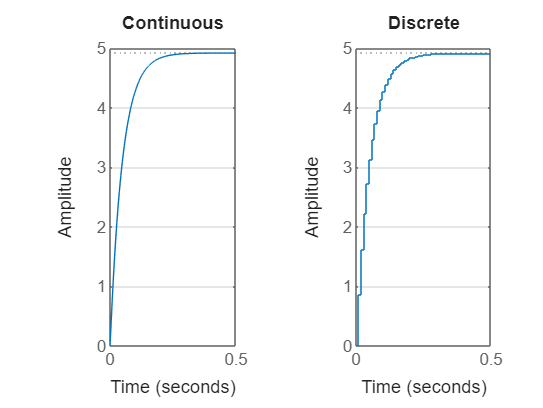

%% Step Response
figure;
subplot(1,2,1);
step(sys_c, 0.5);
title('Continuous');
grid on;

subplot(1,2,2);
step(sys_d, 0.5);
title('Discrete');
grid on;

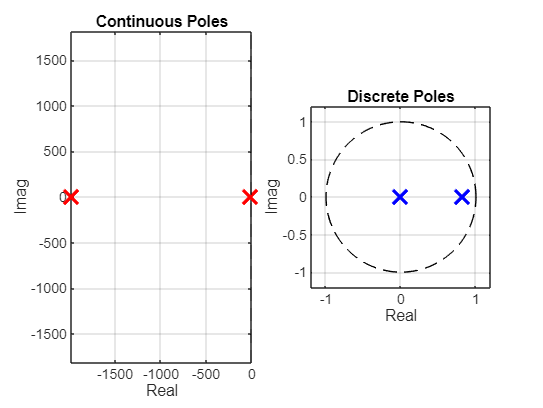

%% Pole Maps
figure;
subplot(1,2,1);
plot(real(lambda), imag(lambda), 'rx', 'MarkerSize', 12, 'LineWidth', 2);
hold on; xline(0, 'k--');
grid on; axis equal;
title('Continuous Poles');
xlabel('Real'); ylabel('Imag');

subplot(1,2,2);
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k--'); hold on;
plot(real(z_poles), imag(z_poles), 'bx', 'MarkerSize', 12, 'LineWidth', 2);
grid on; axis equal;
title('Discrete Poles');
xlabel('Real'); ylabel('Imag');
xlim([-1.2 1.2]); ylim([-1.2 1.2]);

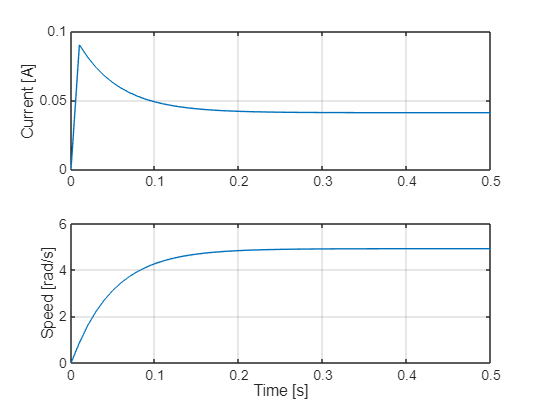

%% Simulate (Discrete)
t = 0:Ts:0.5;
u = ones(size(t));  % Step input
[y, t_out, x] = lsim(sys_d, u, t);

figure;
subplot(2,1,1);
plot(t_out, x(:,1));
ylabel('Current [A]');
grid on;

subplot(2,1,2);
plot(t_out, x(:,2));
ylabel('Speed [rad/s]');
xlabel('Time [s]');
grid on;